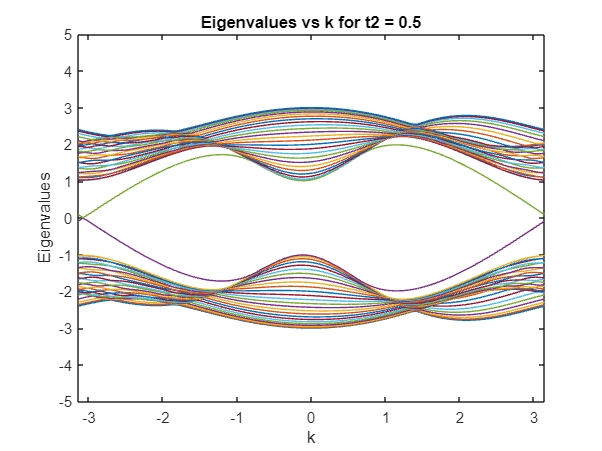

% Define parameters
t1 = 1;
m = 0.2;
Ny = 50;
k_values = linspace(-pi, pi, 100);

% Define t2 values to loop over
t2_values = linspace(0, 0.5, 100); % Adjust as needed

% Initialize video writer
v = VideoWriter('eigenvalues_video.mp4', 'MPEG-4');
v.FrameRate = 4; % Adjust the frame rate as needed
open(v);

% Loop over t2 values
for j = 1:length(t2_values)
    t2 = t2_values(j);

    % Initialize matrix to store eigenvalues
    Eigenvalues = zeros(Ny, numel(k_values));
    %Eigenvalues_test = zeros(Ny, numel(k_values));

    % Calculate eigenvalues for each k value
    for i = 1:numel(k_values)
        Evals_k = Evals(t1, t2, k_values(i), m, Ny);
        Eigenvalues(:, i) = sort(real(Evals_k)); % Sort eigenvalues and store
        %Eigenvalues_test(:, i) = sort(Evals_k); % checked and these are
        %all real!
    end

    % Plotting
    plot(k_values, Eigenvalues);
    xlabel('k');
    ylabel('Eigenvalues');
    title(['Eigenvalues vs k for t2 = ' num2str(t2)]);
    xlim([-pi, pi]);
    ylim([-5, 5]); % Adjust ylim as needed

    % Add frame to video
    frame = getframe(gcf);
    writeVideo(v, frame);
end


% Close video writer
close(v);

function Mass = Mass(M, N)
    % Initialize the Mass matrix
    Mass = diag(-M .* (-1).^(1:N));
end

function H0 = H0(t1, t2, N)
    % Initialize the H0 matrix
    H0 = -(diag(t1 * ones(1, N-1), 1) + diag(t1 * ones(1, N-1), -1) + ...
        diag(1i * t2 * (-1).^floor((0:N-3)/2), 2) + diag(-1i * t2 * (-1).^floor((0:N-3)/2), -2));
end

function H1 = H1(t1, t2, N)
    % Initialize the H1 matrix
    list1 = repmat([0, 0, t1, 0], 1, ceil(N / 4));
    list2 = repmat([t1, 0, 0, 0], 1, ceil(N / 4));
    list3 = repmat([0, -1i * t2, 1i * t2, 0], 1, ceil(N / 4));
    list4 = repmat([1i * t2, 0, 0, -1i * t2], 1, ceil(N / 4));
    H1 = -(diag(1i * t2 .* (-1).^(1:N)) + diag(list1(1:N-1), 1) + diag(list2(1:N-1), -1) + ...
        diag(list3(1:N-2), 2) + diag(list4(1:N-2), -2));
end

function Evals = Evals(t1, t2, k, M, N)
    % Calculate the matrices H0 and H1
    H0_matrix = H0(t1, t2, N);
    H1_matrix = H1(t1, t2, N);

    % Declare E a variable
    %syms E

    % Calculate the eigenvalues
    Evals = eig(H1_matrix * exp(-1i * k) + H0_matrix + ...
        ctranspose(H1_matrix) * exp(1i * k) + Mass(M, N));
    %determ = det(H1_matrix * exp(-1i * k) + H0_matrix + ... 
    %    ctranspose(H1_matrix) * exp(1i * k) + Mass(M, N) + E * eye(N));
    %Evals = solve(determ,E);
end